rosshutdown();

Shutting down global node /matlab_global_node_09030 with NodeURI http://192.168.178.112:64867/ and MasterURI http://192.168.178.125:11311.


setenv('ROS_MASTER_URI', 'http://192.168.178.125:11311');
setenv('ROS_IP', '192.168.178.112');
rosinit('192.168.178.125');

The value of the ROS_IP environment variable, 192.168.178.112, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_90283 with NodeURI http://192.168.178.112:65273/ and MasterURI http://192.168.178.125:11311.


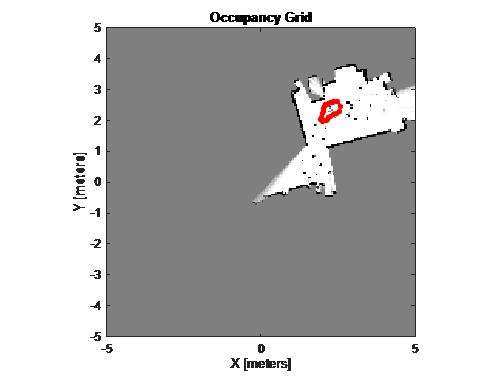


lidarSub = rossubscriber('/scan', 'sensor_msgs/LaserScan');



hFigMap = figure;
% axMap = axes(Parent=hFigMap);

maxLidarRange = 12;
gridResolution = 20;
slamObj = lidarSLAM(gridResolution, maxLidarRange);
slamObj.LoopClosureThreshold = 210; % Optional: Adjust for better loop closure detection
slamObj.LoopClosureSearchRadius = 8; % Optional: Adjust based on environment
xlimit = [-5, 5];
ylimit = [-5, 5];
lidarOffset = [2, 2]; 
while ishandle(hFigMap)
   
    
    scans  = receive(lidarSub, 2);

    range = scans.Ranges;
    angle = linspace(scans.AngleMin, scans.AngleMax, numel(range));
        
    scan = lidarScan(range, angle);

     
    map2 = addScan(slamObj,scan);
    if ~map2
        continue;
    end
    [scanSlam, poses] = scansAndPoses(slamObj);
    
    poses(:, 1:2) = poses(:,1:2) + lidarOffset;
    occMap = buildMap(scanSlam,poses,gridResolution,maxLidarRange);
    
    ax = axes(parent=hFigMap);
    show(occMap, parent=ax);
    hold(ax, 'on');
    plot(ax, poses(:,1), poses(:,2), 'r', 'LineWidth', 2);
    plot(ax, poses(:,1), poses(:,2), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r');
    hold(ax, 'off');
    xlim(ax, xlimit);
    ylim(ax, ylimit);
    

    
    drawnow;

end